# `Generic Genetic Algorithms`

## 16/03/2021

### Libby Pariente, Jan-Felix De Man

### Intelligent Systems

# Knapsack Problem

### The following section focuses on solving the knapsack problem:

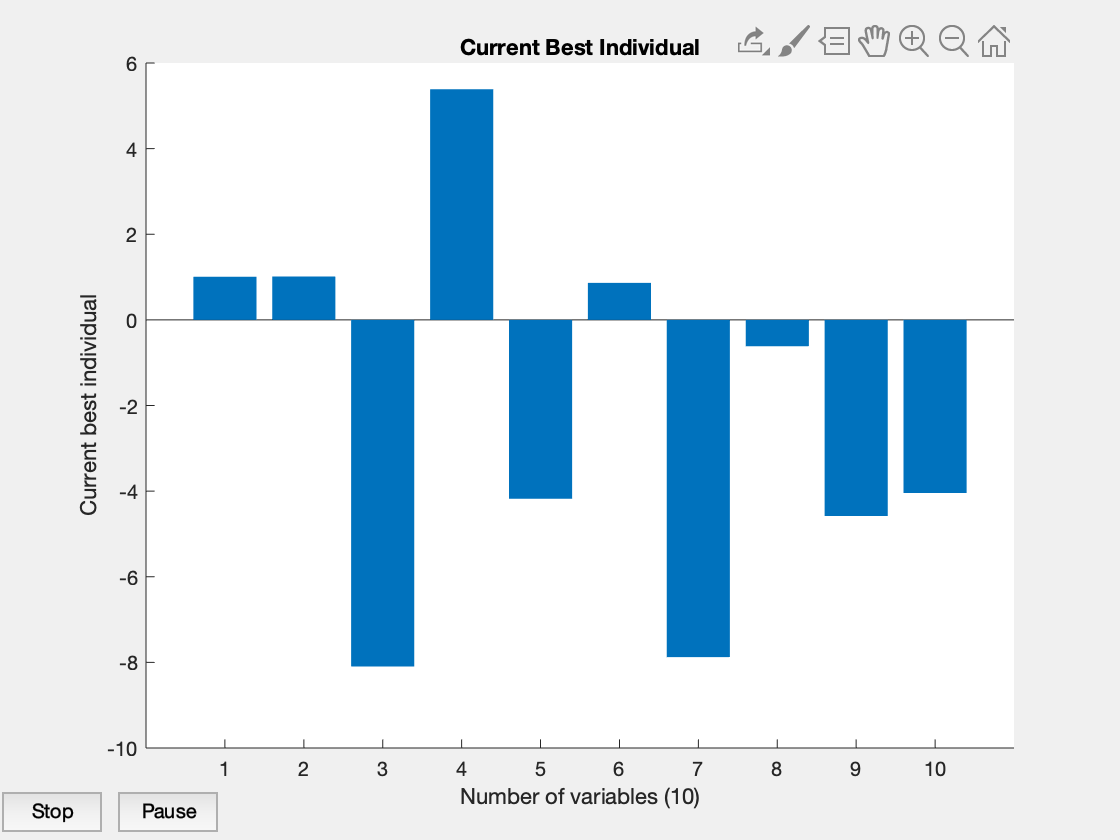

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


nvars=10;
lb = [0,0];
ub = [3,3];

option = optimoptions('ga');

option1 = optimoptions(option,'PlotFcn','gaplotbestindiv', 'Generation',Inf);
option2 = optimoptions(option,'PlotFcn',{@gaplotbestf,@gaplotchange});

vectorizedoption = optimoptions(option,'UseVectorized',true);

rng(100);

[xvec1,fvalvec1,exitflagvec1,outputvec1,populationvec1,scorevec1] = ga(@(x) vectorized_fitness(x,100,1),nvars,[],[],[],[],lb,ub,[],option1);

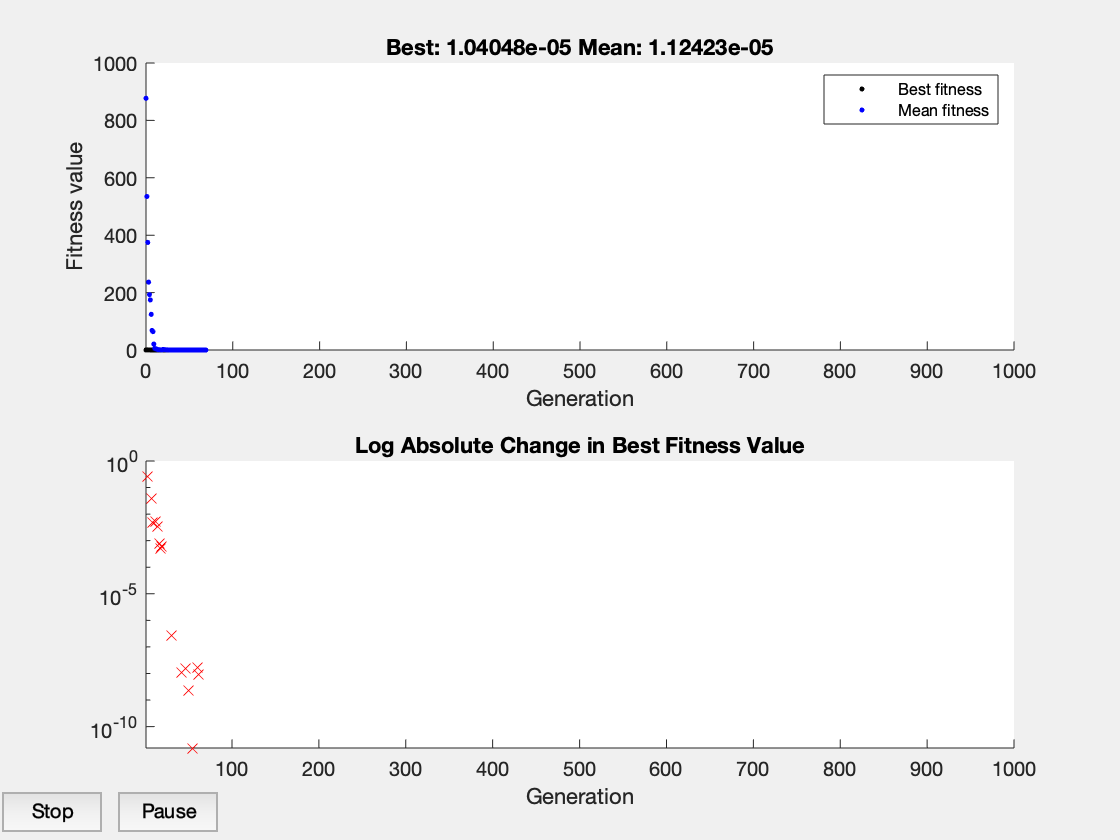

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


[xvec2,fvalvec2,exitflagvec2,outputvec2,populationvec2,scorevec2] = ga(@(x) vectorized_fitness(x,100,1),nvars,[],[],[],[],lb,ub,[],option2);

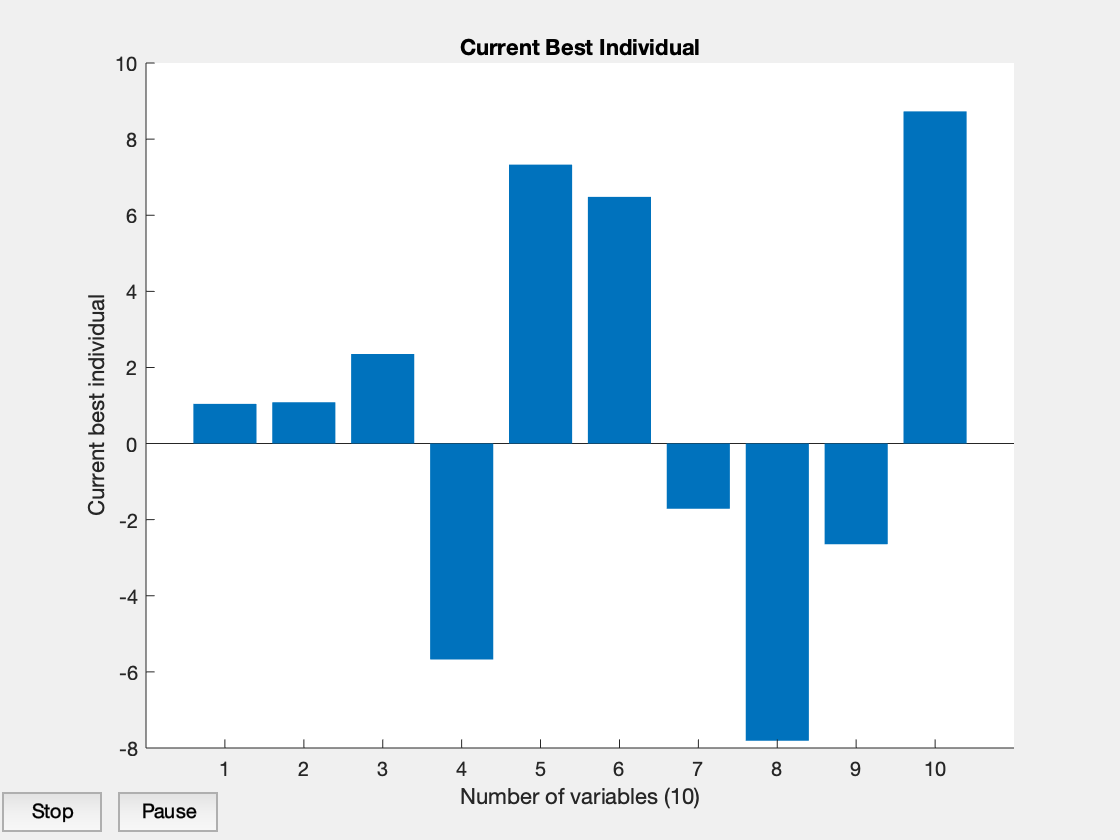

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.



[xsimp1,fvalsimp1,exitflagsimp1,outputsimp1,populationsimp1,scoresimp1] = ga(@simple_fitness,nvars,[],[],[],[],lb,ub,[],option1);

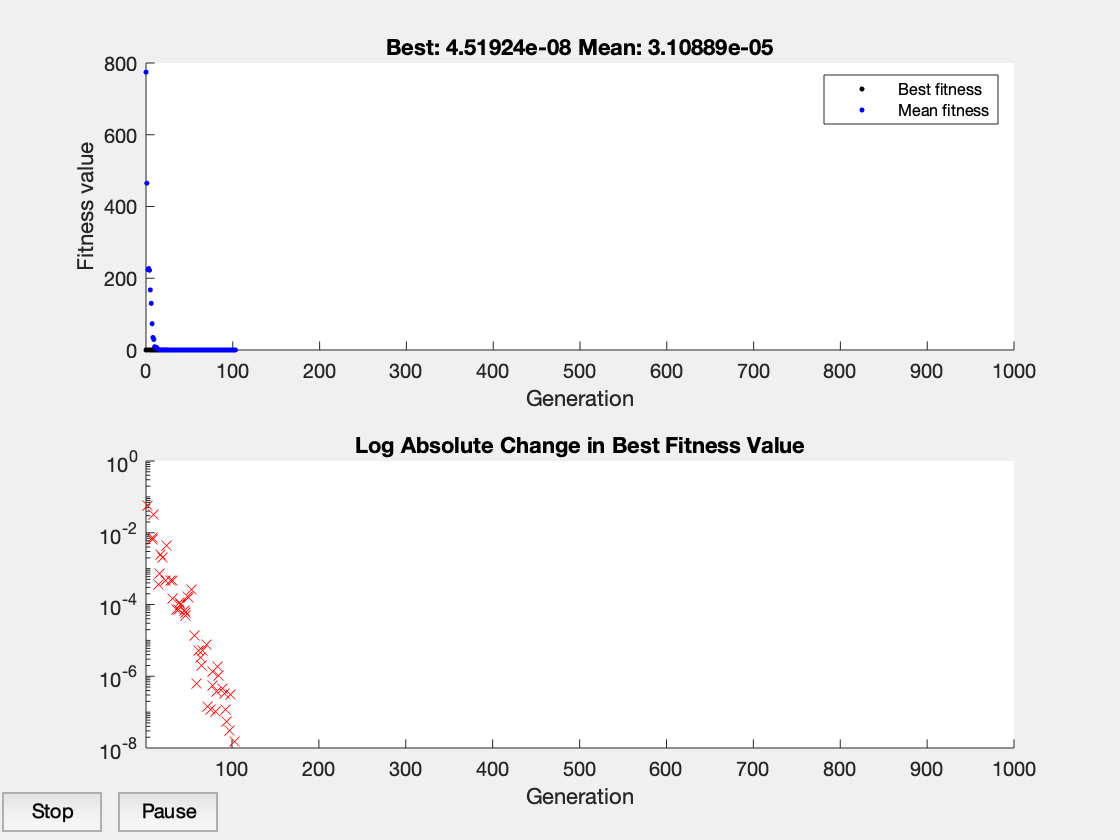

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


[xsimp2,fvalsimp2,exitflagsimp2,outputsimp2,populationsimp2,scoresimp2] = ga(@simple_fitness,nvars,[],[],[],[],lb,ub,[],option2);

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization termina

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


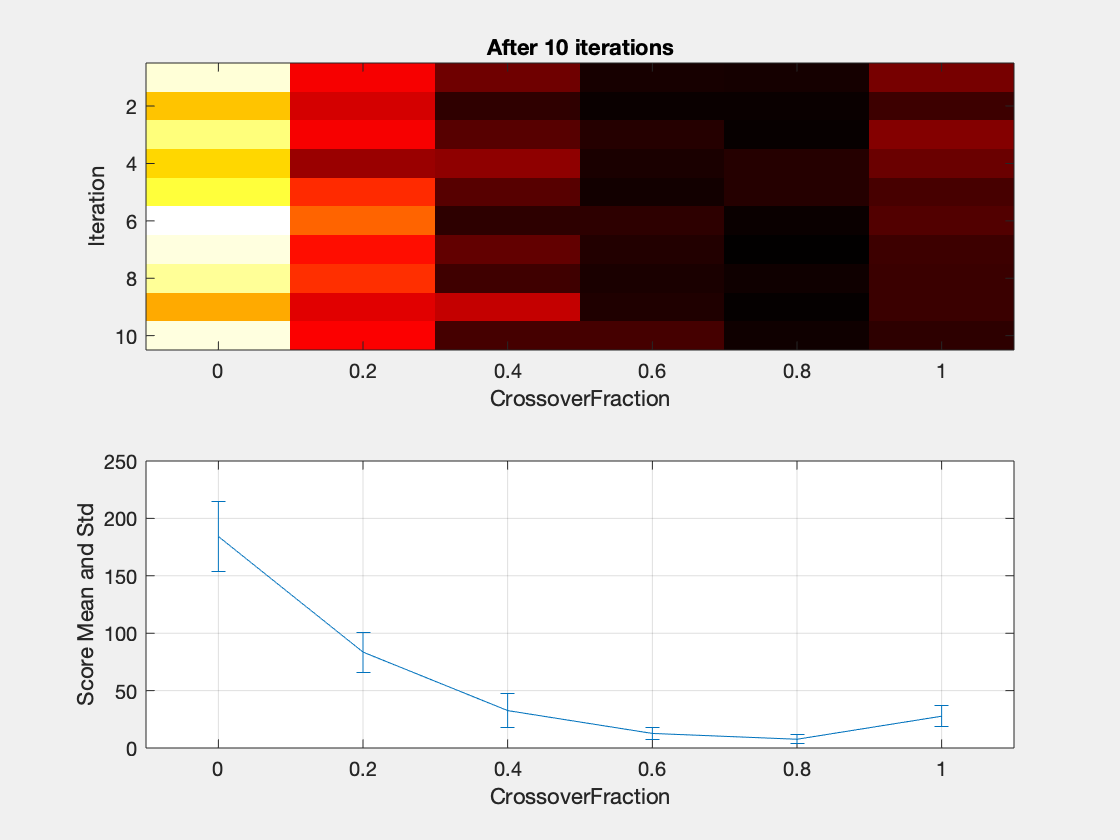


deterministicstudy;

The results are presented vectorized and not to see the difference between the permutated and unpermutated genome. 

The vectorization allows permutation of the gene. Therefore when looking for mutations over generations this is useful. 

### To interpret: 

#### Vectorized:

4 best individuals; we can se the overall change in fitness over generations which becomes increasingly lower, this is due to not pruning the reproductions of the individuals. 

#### Unvectorized:

6 best individuals; the best fitness value is higher but takes longer to compute. 

#### Results:

Using unvectorized fitness function is better. 

Thr knapsack problem is solved and we can see after 10 iterations the change in the crossover function, meaning, the reproduction function. The graphs show us that we get worse results with each iteration, though this makes sense as all that is needed is one bad fitness "parent" to have worse fitness children. For this we present the optimal traveling salesman problem next.

# Traveling Salesman Problem

## The following section focuses on solving the traveling salesman problem:

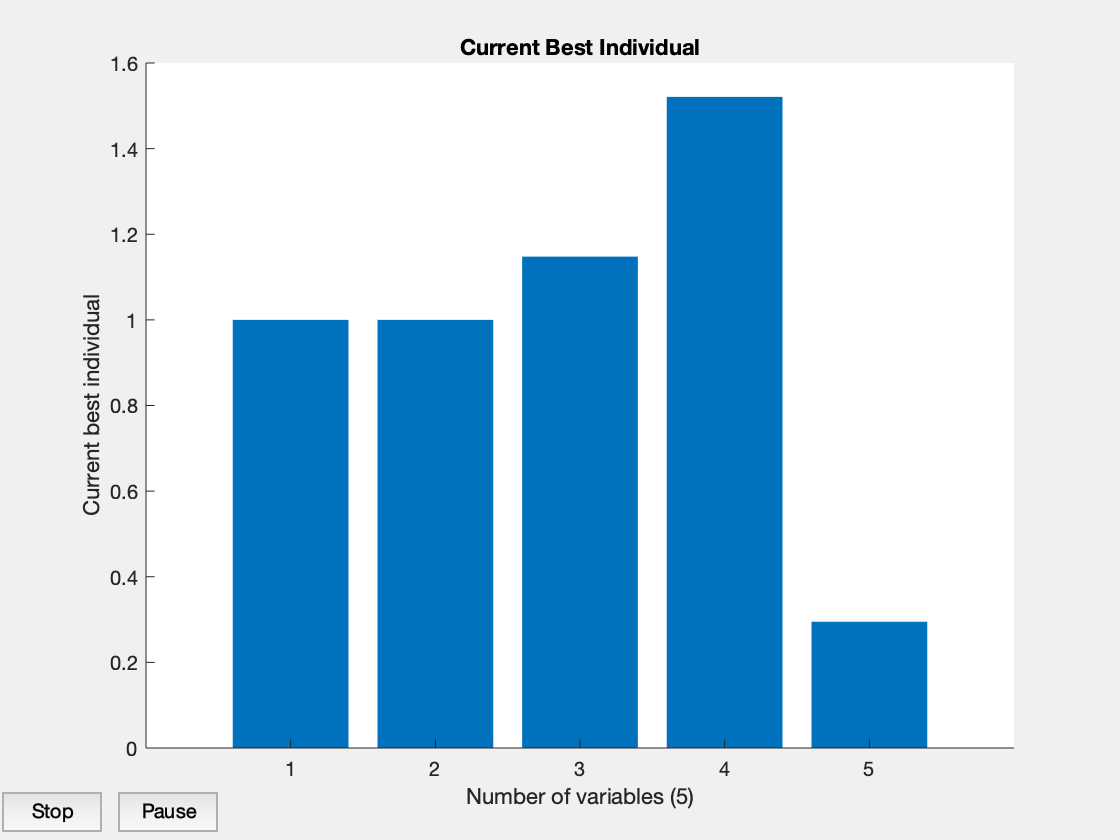

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


mvars = 5;
popusize = 50;
optiontravel = optimoptions('ga');
scalingfitness = optimoptions(optiontravel,'FitnessScalingFcn',{@fitscalingtop,popusize});

optionbest = optimoptions(scalingfitness,'PlotFcn','gaplotbestindiv');
optionbest2 = optimoptions(scalingfitness,'PlotFcn',{@gaplotbestf,@gaplotchange});

[xsimp11,fvalsimp11,exitflagsimp11,outputsimp11,populationsimp11,scoresimp11] = ga(@simple_fitness,mvars,[],[],[],[],lb,ub,[],optionbest);

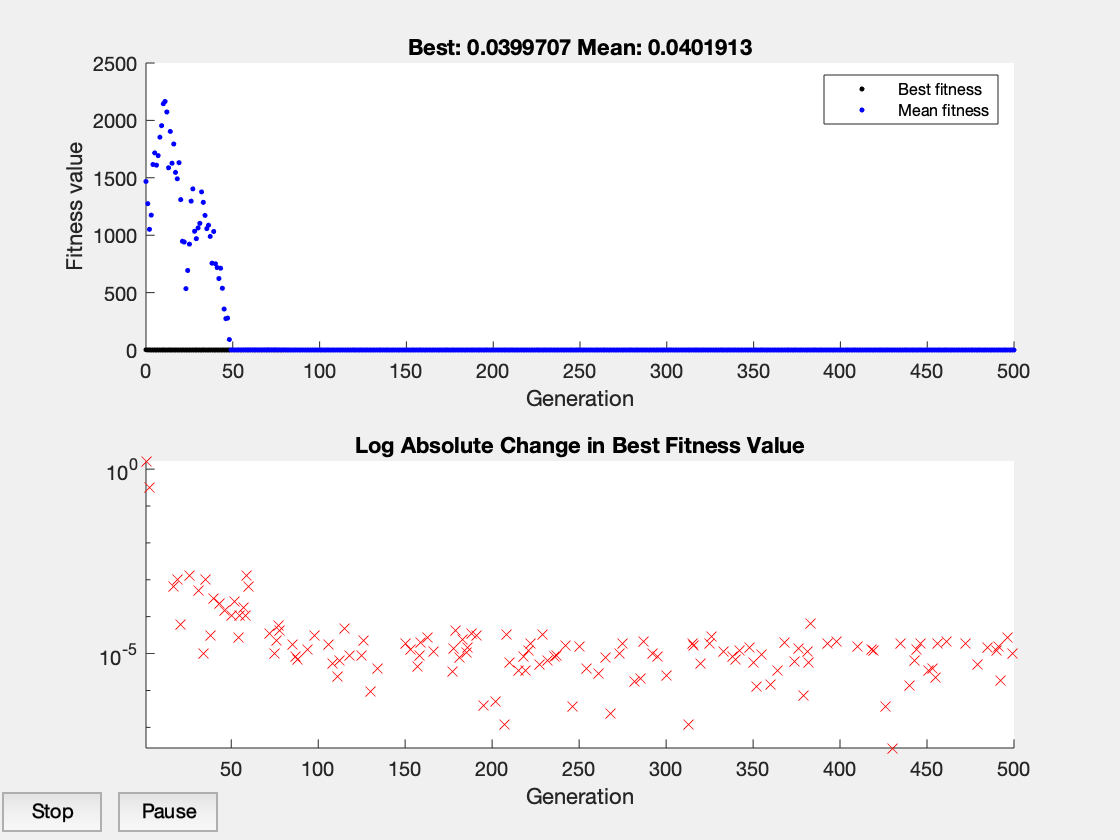

Optimization terminated: maximum number of generations exceeded.


[xsimp21,fvalsimp21,exitflagsimp21,outputsimp21,populationsimp21,scoresimp21] = ga(@simple_fitness,mvars,[],[],[],[],lb,ub,[],optionbest2);

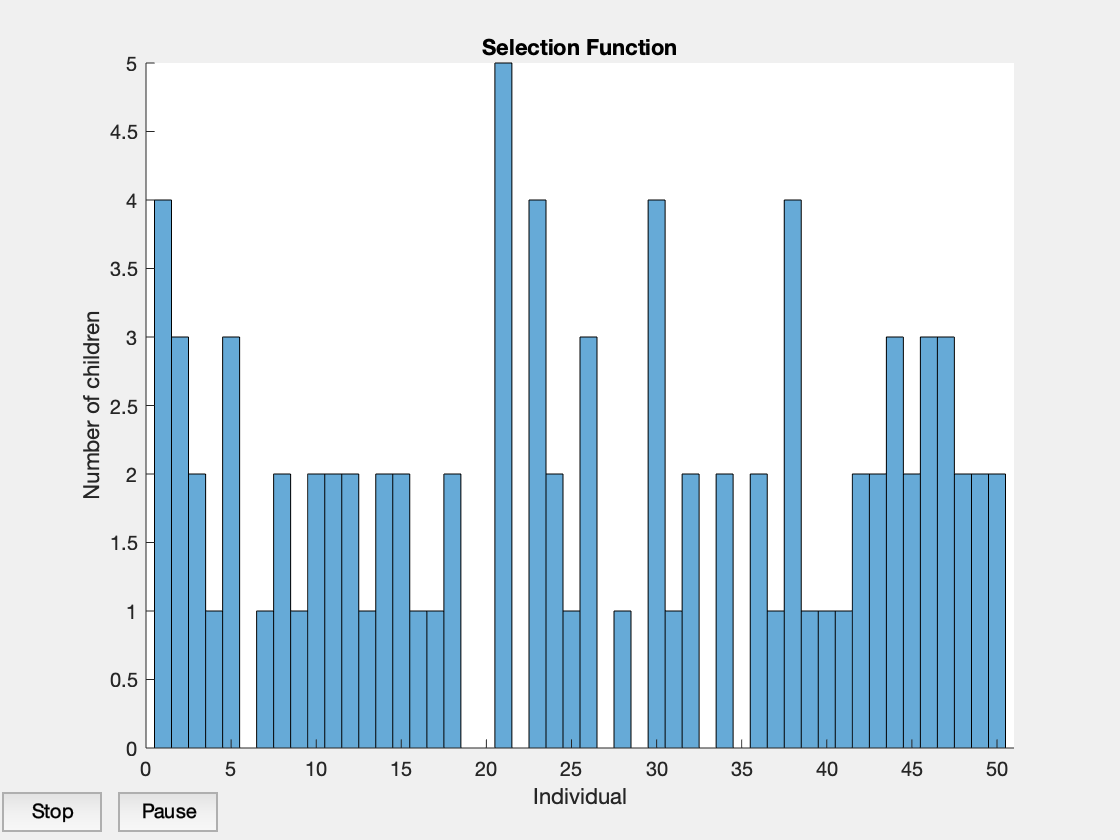

Optimization terminated: maximum number of generations exceeded.



%[xvec11,fvalvec11,exitflagvec11,outputvec11,populationvec11,scorevec11] = ga(@(x) vectorized_fitness(x,100,1),mvars,[],[],[],[],lb,ub,[],optionbest);
%[xvec21,fvalvec21,exitflagvec21,outputvec21,populationvec21,scorevec21] = ga(@(x) vectorized_fitness(x,100,1),mvars,[],[],[],[],lb,ub,[],optionbest2);


option111 = optimoptions(scalingfitness,'SelectionFcn',{@selectiontournament,popusize});
option11 = optimoptions(option111,'PlotFcn','gaplotselection');

[xsimp111,fvalsimp111,exitflagsimp111,outputsimp111,populationsimp111,scoresimp111] = ga(@simple_fitness,mvars,[],[],[],[],lb,ub,[],option11);

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization termina

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


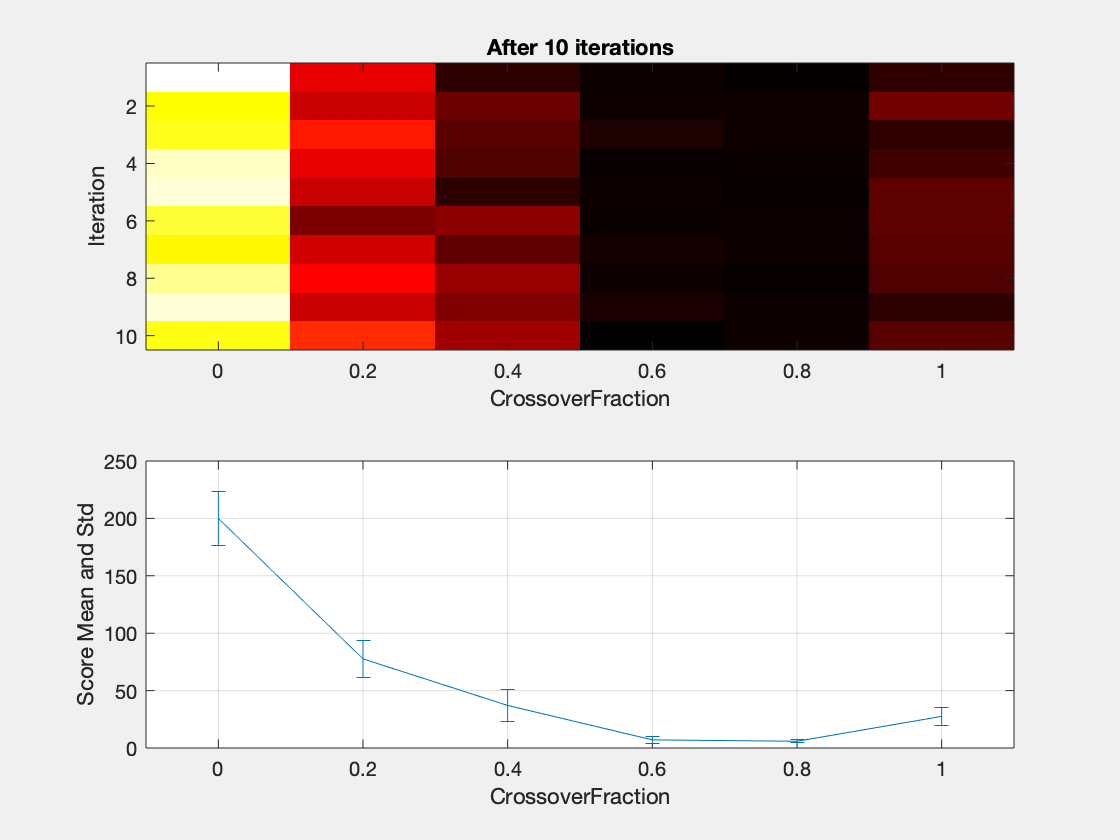


%[xvec111,fvalvec111,exitflagvec111,outputvec111,populationvec111,scorevec111] = ga(@(x) vectorized_fitness(x,100,1),mvars,[],[],[],[],lb,ub,[],option11);

deterministicstudy;

For this problem we take a smaller population of 50, by selecting number of variables checked to be 5. 

We set the scaling fitness function to the default one by MatLab and plot the best individuals. (Due to the worse results with vectorized we only look at the simple fitness function, the vectorized one is commented though). 

The best fitness grows smaller with the population but starts quite high which allows the understanding that we do have the best individuals and they are able to reproduce between them, especially considering the best fitness value is high. 

We can see the changes of the score and std after every iteration. 